# **[2024-1 디지털제어 MATLAB 예제] **

# **Unit 2: Ch. 2. Discrete-time Systems and the Z-transforms - Part A**

- 본 파일은 2024년 1학기 서울시립대학교 전자전기컴퓨터공학부 디지털제어 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 조교

- **교과목 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- MATLAB version : 2023a 이상 (2022b 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

#### 문제 1 : Delay operator의 이해 

문제 1에서는 MATLAB 상에서 inverse Z-transform을 연산하는 방법과, delay 연산자인 $z^{-1}$의 역할에 대해 이해해봅니다. 

Z-transform 관련 예제에서는, symbolic 연산을 활용할 예정입니다.

아래와 같이 초기화합시다.

clc; clear all; close all;
syms k z
N = 20;

이제 iztrans 함수를 이용하여, $F^d(z)=\frac{\sin(0.5)z}{z^2-2\cos(0.5)z+1}=\mathcal{Z}^{-1}(\sin(0.5k))$의 inverse Z-transform $f^d(k)$을 아래와 같이 계산합니다.

Fdz = (z*sin(0.5))/(z^2 - 2*z*cos(0.5)+1);
fdk = iztrans(Fdz,k); 
fdk = simplify(fdk);
fdk_data = subs(fdk,k,0:N);
fdk_data = double(fdk_data);

유사한 방식으로, $G^d(z)=z^{-1}F^d(z)$의 inverse Z-transform $g^d(k)$을 아래와 같이 계산합니다.

Gdz = Fdz * z^-1;
gdk = iztrans(Gdz,k);
gdk = simplify(gdk);
gdk_data = subs(gdk,k,0:N);
gdk_data = double(gdk_data);

Z-transform에서 $z^{-1}$가 가지는 의미를 생각해볼 때, $g^d(k)=f^d(k-1){\bf 1}^d(k-1)$임을 유추해볼 수 있습니다. 

아래 그림을 통해 실제로 그러한지를 확인할 수 있습니다.

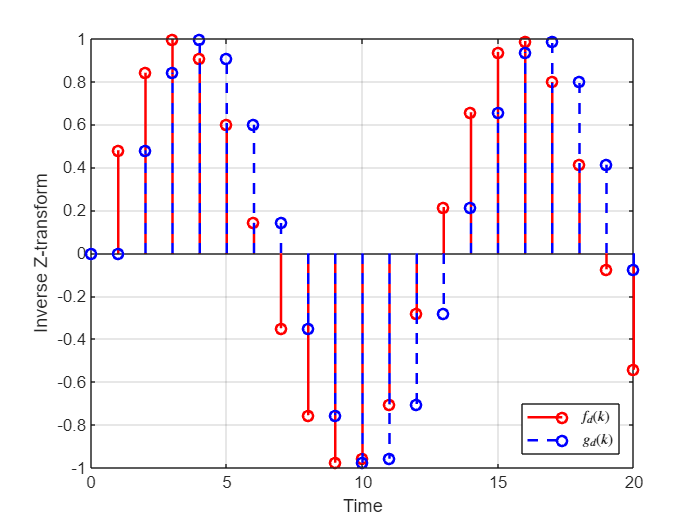

fig = figure();     
stem(0:N,fdk_data,'r','LineWidth',1.5);
hold on;
stem(0:N,gdk_data,'--b','LineWidth',1.5);
grid on;
xlabel('Time');
ylabel('Inverse Z-transform');
legend('$f_{d}(k)$','$g_{d}(k)$','Interpreter','latex','Location','southeast');

#### 문제 2 : 연속시간 신호의 이산화

문제 2에서는 주어진 연속시간 신호를 이산화하는 방법에 대해 알아보겠습니다. 

Symbolic 연산을 위해 아래를 정의합니다.

clc; clear all; close all;
syms t k z;

샘플링 주기 $T=(\pi/6)~{\rm sec}$로 하고, 연속시간 신호인 $f(t)=\sin(t)$를 다음과 같이 이산화합니다.

f = sin(t);
T = pi/6;
fdk = subs(f,t,k*T);

이들을 하나의 화면에 그리면 다음과 같습니다.

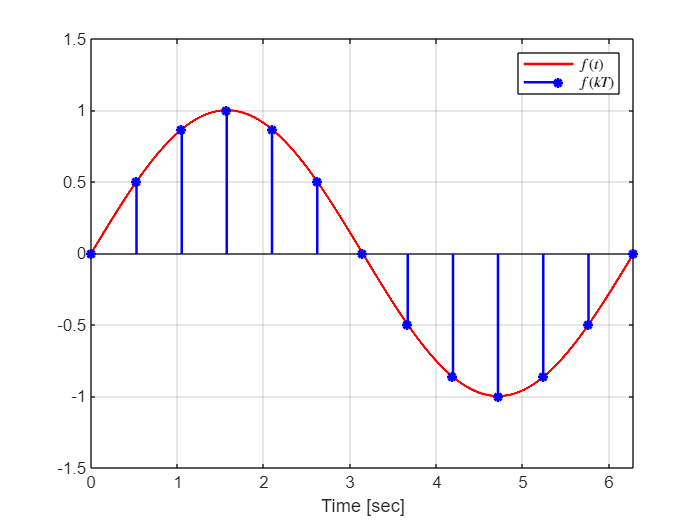

N = 12;
fdk_data = double(subs(fdk,k,0:N));

figure();
dt = 0.001;
f_data = subs(f,t,0:dt:2*pi);
plot(0:dt:2*pi,f_data,'r','LineWidth',1.5);
hold on;
stem(0:T:2*pi,fdk_data,'*b','LineWidth',1.5);
grid on;
xlabel('Time [sec]');
xlim([0,2*pi]); 
ylim([-1.5,1.5]);
legend('$f(t)$','$f(kT)$','Interpreter','latex','Location','northeast'); 

#### 문제 3 : Z-transform의 선형성

이번 문제에서는 Z-transform의 선형성에 대해 살펴보겠습니다.

문제 2와 동일한 샘플링 주기에 대하여 정의된 이산시간 신호들 $f^d(k)=\sin(kT)$, $g^d(k)=\cos(kT)$를 생각해봅시다.

clc; clear all; close all;
syms k z;
T = pi/6;

fdk = sin(k*T);
gdk = cos(k*T);

위 신호의 선형 결합인 $h_1^d(k)=1\cdot f^d(k)+2\cdot g^d(k)$는 다음과 같이 얻을 수 있습니다..

N = 12;
h1dk = 1*fdk + 2*gdk;

지금부터는 $F^d(z):=\mathcal{Z}(f^d(k))$, $G^d(z):=\mathcal{Z}(g^d(k))$에 대하여, 


$$h_2^d(k):=\mathcal{Z}^{-1}(1\cdot F^d(z)+2\cdot G^d(z))$$


가 $h_1^d(k)=1\cdot f^d(k)+2\cdot g^d(k)$와 같음을 보이도록 하겠습니다. 

이를 위해  $h_2^d(k)$를 다음의 연산으로 얻습니다.

Fdz = ztrans(fdk,z); 
Gdz = ztrans(gdk,z);

h2dk = iztrans(1*Fdz + 2*Gdz,k);
h2dk = simplify(h2dk);

이제 두 이산신호를 동시에 그려서 동일함을 확인해봅시다.

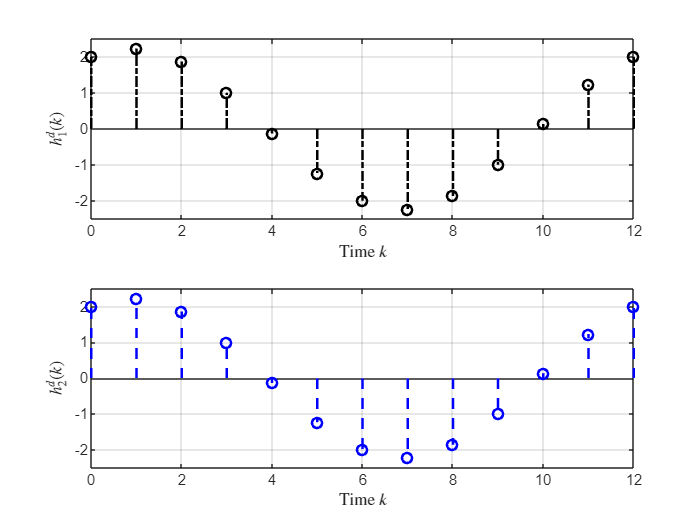

h1dk_data = double(subs(h1dk,k,0:N));
h2dk_data = double(subs(h2dk,k,0:N));

figure();
subplot(2,1,1);
stem(0:N,h1dk_data,'-.k','LineWidth',1.5);
grid on;
xlim([0,N]);
ylim([-2.5,2.5]);
xlabel('Time $k$','Interpreter','latex');
ylabel('$h_1^d(k)$','Interpreter','latex');
hold on;

subplot(2,1,2);
stem(0:N,h2dk_data,'--b','LineWidth',1.5);
grid on;
xlim([0,N]);
ylim([-2.5,2.5]);
xlabel('Time $k$','Interpreter','latex');
ylabel('$h_2^d(k)$','Interpreter','latex');

#### 문제 4 : 전달함수로 표현된 이산시간 시스템의 step response 구하기 

문제 4에서는 $G^d(z)=\frac{z}{z^2-1.7z+0.72}$를 전달함수로 가지는 이산시간 시스템에 대하여, MATLAB/Simulink 환경에서 step response를 구하는 3가지 방법에 대해 알아보겠습니다. 

이를 위해, 먼저 위의 이산 시간 전달함수를 tf 모델 객체의 형태로 구현합시다.

numGdz = [1 0];
denGdz = [1 -1.7 0.72];
Gdz = tf(numGdz,denGdz,-1);

**(아마도 가장 간편한) 첫 번째 방법은, MATLAB에서 제공하는 step 함수를 사용하는 것입니다.**

N = 50;
y1dk = step(Gdz,0:N);

step 함수의 결과는 vector 형의 데이터로 저장됩니다. 

**두 번째 방법은, 앞선 문제들처럼 inverse Z-transform을 활용하는 것입니다. **

이를 위해 unit step 함수로 정의된 $u^d(k)={\bf 1}^d(k)$의 Z-transform을 tf 모델 객체의 형태로 정의하고, 시스템의 전달함수인 $G^d(z)$에 곱하여 출력 $Y^d(z)$를 얻도록 합시다. 

Udz = tf(1,[1 -1],-1);
Y2dz = Gdz*Udz;

이제 앞선 문제들과 동일한 방법을 통해 $Y_2^d(z)=G^d(z)U^d(z)$의 inverse Z-transform을 얻습니다.

[numY2dz,denY2dz] = tfdata(Y2dz);
syms k z
Y2dz_sym = poly2sym(cell2mat(numY2dz),z)/poly2sym(cell2mat(denY2dz),z);
% 위의 코드의 결과는, Y2dz_sym = (numY2dz(1)*z^2 + numY2dz(2)*z +
% numY2dz(3))/(denY2dz(1)*z^2 + denY2dz(2)*z + denY2dz(3))과 동일합니다.
y2dk = iztrans(Y2dz_sym,k);
y2dk = double(subs(y2dk,k,0:N));

**마지막으로, Simulink 환경에서 시간 영역의 모의실험을 수행하는 방법이 있습니다. **

미리 작성해둔 Simulink 파일을 열어봅시다.

open('sim_Prob4.slx');

Simulink 파일은 아래와 같이 구성되어 있으며, 이 중 discrete transfer function 블록을 통해 이산시간 시스템을 구현할 수 있습니다.

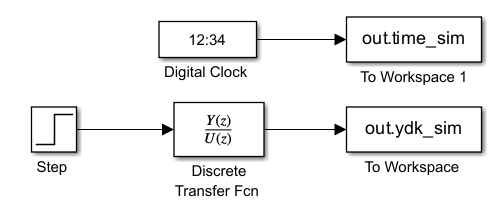

Discrete transfer function 블록을 더블 클릭하면, 다음의 창이 열립니다. 

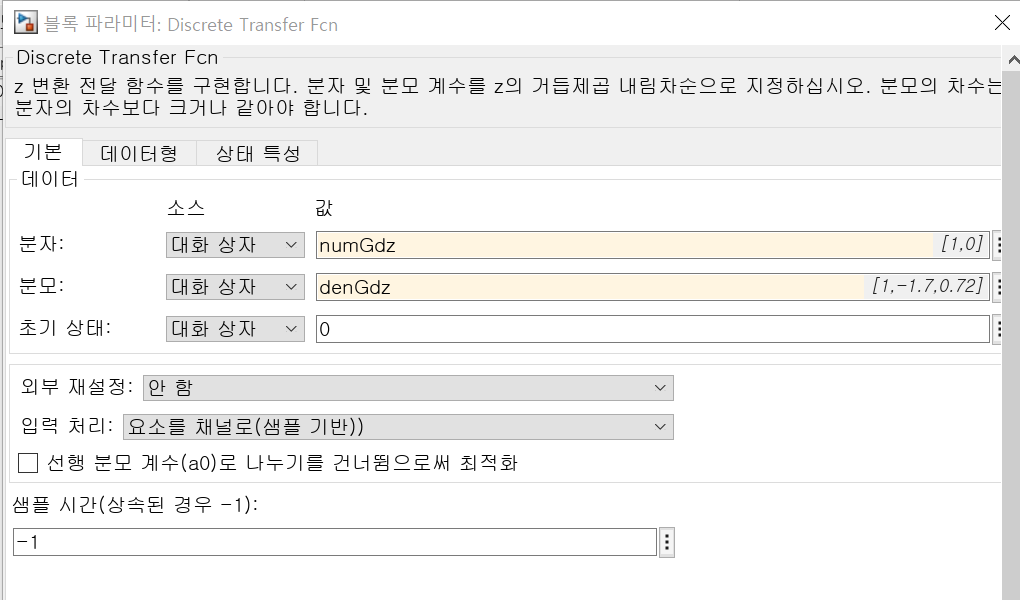

여기서 전달함수의 분자식, 분모식의 계수와 관련된 numGdz, denGdz 벡터를 입력하면, 이산시간 전달함수 $G^d(z)$를 Simulink 환경에서 구현할 수 있게 됩니다.

(구체적으로 샘플 시간 혹은 샘플링 주기를 정하지 않았다면, -1로 하여도 무방합니다.)

이제 sim 함수를 이용하여 시뮬레이션을 수행하고, 그 결과를 MATLAB의 작업 공간에 저장합시다.

sim('sim_Prob4.slx');

simout = ans;
time_sim = simout.time_sim;
y3dk = simout.ydk_sim;

이제 그림을 통해 모든 결과가 동일함을 확인해봅시다. 

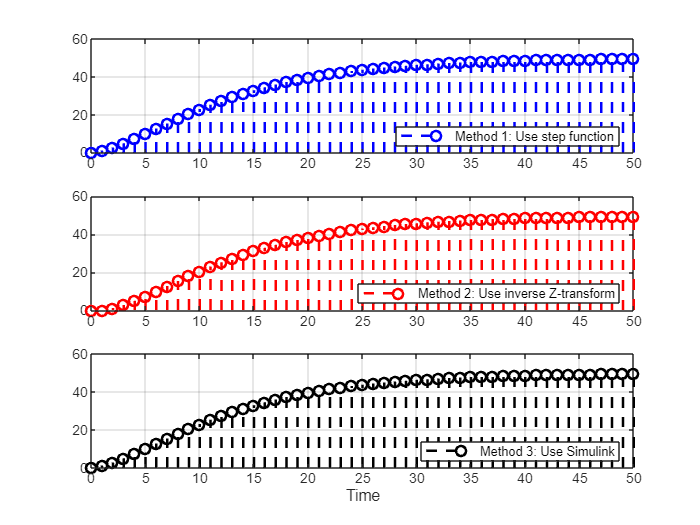

figure();
title('Step responses')
subplot(3,1,1)
stem(0:N,y1dk,'--b','LineWidth',1.5);
grid on;
legend('Method 1: Use step function','Location','southeast');
subplot(3,1,2)
stem(0:N,y2dk,'--r','LineWidth',1.5);
grid on;
legend('Method 2: Use inverse Z-transform','Location','southeast');
subplot(3,1,3)
stem(time_sim,y3dk,'--k','LineWidth',1.5);
legend('Method 3: Use Simulink','Location','southeast');
grid on;
xlim([0,N]);
xlabel('Time');